**Given: **

%Measurement L, Error Free X,  Function Model

**Wanted:   Solved by Matrix Computation**

%Unknown X, Residual
addpath Template_data\
addpath Function\
addpath Semester_2nd_data\
clearvars

**Input Data**

Elist=["Free_=||"
    "Free_data=[]"
    "L_=|Ext('7dis2.txt','DIS','DIS')|Ext('7dir2.txt','DIR','DIR')|"
    "L_data=[Ext('7dis2.txt','DIS','DIS');u2u('1gon')*Ext('7dir2.txt','DIR','DIR')]"
    "X_=|Ext('7new2.txt','y:x','PTYX')|Ext('7dir2.txt','w','W')|"
    "X_data=[Ext('7new2.txt','y:x','PTYX');Ext('7dir2.txt','w','W')]"
    "LB_=|cons [3 1]|"
    "LB_data=[zeros(3 ,1)]"    
    ];

AnalyzeEList(Elist);

% Stochastic

[Var_ind,Var_name]=findVar();
S_L=expand_V(ones(size(L_)),Var_ind,u2u("1mm 1mgon"));  


% Function 
F_ = [Get_Funlist(DIS,{"x","y"},"DIS")
    Get_Funlist(DIR,{"x","y","w"},"DIR")]; 
 
FB_=[sum(y)
    sum(x)
    xyRotation(y,x)
    ];  

list_info=definedatum("x:y",[1000, 2000, 3000],"norm");  % decide if B are pratia
cons_info=add_constraint("B",FB_);

**Measurment and Stochastic**

checkConfig();

The angle in L_. 


ans = table
        Var1     
    _____________

    [1×17 string]


... will be generate F_m
... converted to gon 
The angle in X_. 


ans = table
        Var1    
    ____________

    [1×7 string]


... will be converted to gon 


if ~isempty(L_i)
    F_m=F_;
    F_m(L_i)=mod(F_(L_i),2*pi);
else
    F_m=F_;
end
%Number of observations
no_n =  length(L_); 
%Number of unknowns
no_u = length(X_);
%Redundancy
redundancy = no_n-no_u;

% 4.Function Model
disp("=========================")

disp("1. Observation Vector") 

1. Observation Vector


disp("=========================")

if ~exist("dash")
    dash=[0];
end
L_dash_=L_+dash;
L_==L_data+dash

F_=F_+dash;
F_m=F_m+dash;
disp("=========================")

disp("2. Stochastic Model") 

2. Stochastic Model


disp("=========================")

sigma_0 =1;
if ~exist("S_LL")
    S_LL = diag(S_L.^2);
    
end
if ~exist("S_L")
    S_L = diag(S_LL);
end

%Cofactor matrix of the observations
Q_LL = 1/sigma_0^2*S_LL;
%Weight matrix
P_LL = inv(Q_LL); 
diag(L_.^2);



**Get Function**

if exist("cons_info","var")
    disp("=========================")
    disp("3.Constraint Model") 
    disp("=========================")
    
    B_=cons_info{1};
    display(cons_info{4})
    if ~isempty(cons_info{2})
        FB_=cons_info{2};
        Cons_model=FB_==LB_data
    end
    B_
    no_b=size(B_);
    no_b=no_b(1);
    redundancy = no_n-no_u+no_b;
end

3.Constraint Model


    "Trace formula, B is formed by geography"



$$Cons\_model = \left(\begin{array}{c} y_{1000}+y_{2000}+y_{3000}=0\\ x_{1000}+x_{2000}+x_{3000}=0\\ x_{1000}\,\bar{\mathrm{y1000o}}-y_{1000}\,\bar{\mathrm{x1000o}}+x_{2000}\,\bar{\mathrm{y2000o}}-y_{2000}\,\bar{\mathrm{x2000o}}+x_{3000}\,\bar{\mathrm{y3000o}}-y_{3000}\,\bar{\mathrm{x3000o}}=0 \end{array}\right)$$

$$B\_ = \left(\begin{array}{ccccccccccccccccccccc} 1 & 1 & 1 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & 1 & 1 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ -\bar{\mathrm{x1000o}} & -\bar{\mathrm{x2000o}} & -\bar{\mathrm{x3000o}} & 0 & 0 & 0 & 0 & \bar{\mathrm{y1000o}} & \bar{\mathrm{y2000o}} & \bar{\mathrm{y3000o}} & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$


disp("Redundancy:")

Redundancy:


redundancy

redundancy =     16


disp("=========================")

disp("3.Function Model") 

3.Function Model


disp("=========================")


L_dash_==F_



% Observation Equation
disp("=========================")

disp("4.Observation Equation") 

4.Observation Equation


disp("=========================")

V_=F_-L_dash_;

% Get Design Matrix
A_=jacobian(V_,X_);


disp("O=vTPv--->min") 

O=vTPv--->min


% Get Design Matrix


**Measurement and Redundancy**

% 6.Measurement L
Ndeal(L_, L_data)
% 7.Free Error X
Ndeal(Free_, Free_data)
% 8.Initial values for the unknowns
Ndeal(X_, X_data)
if exist("LB_","var"),Ndeal(LB_, LB_data); end
if exist("X_O","var"),Ndeal(X_O, X_data); end
 

**Adjustment**


L_0=eval(L_);
V_0=eval(V_);
L_dash_0=eval(L_dash_);
X_0=eval(X_);
L_dash_hat=eval(L_dash_);

%break-off conditions
epsilon = 10^-5;
delta = 1e-9;
iteration = 0;
max_xsmall_hat=10^Inf;
syms thx
safe=thx;
thx=0;
checkVCE=true;
vce_iter=0;

if VCE_CONFIG==true
% initial values
    a_all=expand_V(zeros(size(L_)),Var_ind,1*ones(length(Var_ind),1));
    s_o_all=expand_V(zeros(size(L_)),Var_ind,10^10*ones(length(Var_ind),1));
end
%VCE
while checkVCE
    vce_iter=vce_iter+1;
    
    if VCE_CONFIG==true
        %Iteration 1
        checkVCE=sum(abs(s_o_all-1)>10^-4)~=0;
        %VC Matrix of the observations
        C_LL_all=diag(a_all.^2.*S_L.^2);
        %Cofactor matrix of the observations
        Q_LL=1/sigma_0^2*C_LL_all;
        P_LL = inv(Q_LL); 
    else
        checkVCE=0;
    end
        
    max_xsmall_hat=10^Inf;
    while  max_xsmall_hat>epsilon || max(abs(L_dash_hat-eval(F_m)))>delta
         
        iteration=iteration+1;
        A_evl=eval(A_+safe);
        l_vec=L_dash_0-eval(F_m); % vector of reduced observation
    
        %Normal matrix
        N = A_evl'*P_LL* A_evl; 
        n = A_evl'*P_LL*l_vec;
        if exist("cons_info","var")
            
     
            if cons_info{3}=="B"
                B_evl=eval(B_+safe);  
                n_ext = [n;zeros(no_b,1)];
                
            elseif cons_info{3}=="G"
                B_evl=eval(B_+safe);  
                n_ext = [n;zeros(no_b,1)];
                
            elseif cons_info{3}=="g_inv"
                B_evl=eval(B_+safe);  
                n_ext = [n;zeros(no_b,1)];
                
            elseif cons_info{3}=="pseudo"
                [v lambda] = eig(N); 
                B_evl=v(:,find(diag(lambda)<0.000001))';
                no_b=size(B_evl);
                no_b=no_b(1);
                redundancy = no_n-no_u+no_b;
                n_ext = [n;zeros(no_b,1)];
                
            elseif cons_info{3}=="fullrank"
                B_evl=eval(B_+safe);  
                n_ext = [n;eval(LB_)-eval(FB_)];
            else
                error("flag is not right")
        
            end
            
            N_ext=[N B_evl';B_evl zeros(no_b,no_b)];
            Q_xx_ext = inv(N_ext);
            %n_ext = [n;zeros(no_b,1)];
            
            %Inversion of normal matrix / Cofactor matrix of the unknowns
            
            Q_XX = Q_xx_ext(1:no_u,1:no_u);    
            %Solution of normal equation
            X_smallhat=Q_xx_ext*n_ext;  
            max_xsmall_hat=max(abs(X_smallhat(1:no_u)));
            V_hat = A_evl*X_smallhat(1:no_u)-l_vec;
            %
            Ndeal(X_,X_smallhat(1:no_u)+eval(X_));
        else
            %Vector of right hand side of normal equations
            
            %Inversion of normal matrix / Cofactor matrix of the unknowns
            Q_XX = inv(N);    
            %Solution of normal equation
            X_smallhat=Q_XX*n;     
            max_xsmall_hat=max(abs(X_smallhat));
            Ndeal(X_,X_smallhat+eval(X_));
            V_hat = A_evl*X_smallhat-l_vec;
            
        end
        
        V_hat_rad=V_hat;
        % Update v
        Ndeal(L_,L_0+V_hat);
        
        L_dash_hat = L_dash_0+V_hat;
        L_hat=L_0+V_hat;
        X_hat=eval(X_);
        Ndeal(X_O,X_hat);
        %Objective function
        vTPv = V_hat'*P_LL*V_hat;
    
        if iteration > 35
            error("Wrong")
        elseif vce_iter > 20
            error("Wrong VCE")
        end
    end
     
    %Empirical reference standard deviation
    s_0 = sqrt(vTPv/(redundancy));     %a posteriori
    %VC matrix of adjusted unknowns
    S_XX_hat = s_0^2*Q_XX;
    %Cofactor matrix of adjusted observations
    Q_LL_hat = A_evl*Q_XX*A_evl';
    %VC matrix of adjusted observations
    S_LL_hat = s_0^2*Q_LL_hat;
    %Cofactor matrix of the residuals
    Q_vv = Q_LL-Q_LL_hat;
    %VC matrix of residuals
    S_vv = s_0^2*Q_vv;
    
    S_v=sqrt(diag(S_vv));
    S_X=sqrt(diag(S_XX_hat));
    S_L_hat=sqrt(diag(S_LL_hat));
    
    %Check VCE 
    Q_vvP = Q_vv*P_LL;
    if VCE_CONFIG==true       %~exist("Var_ind")
        %[Var_ind,Var_name]=findVar();

        for i =1:length(Var_ind)
            P_dist=P_LL(Var_ind{i},Var_ind{i});
            Q_vvP_dist=Q_vvP(Var_ind{i},Var_ind{i});
            %Sub-vectors of residuals
            v_dist = V_hat_rad(Var_ind{i},1);          %sub-vector of v
            %Compute trace for sub-matrices Q_vvP_dist and Q_vvP_dir
            r_dist = trace(Q_vvP_dist);
            s_o_dist(i,1) =sqrt((v_dist'*P_dist*v_dist)/r_dist);
        end
 
        s_o_all=expand_V(zeros(size(L_)),Var_ind,s_o_dist);
        a_all=a_all.*s_o_all;
    end

end

if exist("cons_info",'var')
    rank_deficient=size(N);
    rank_deficient=rank_deficient(1)-rank(N)
    check_condition=LB_data-eval(FB_)
end

rank_deficient =      3


check_condition = 	1.0e+-13 *

   0.426325641456060
  -0.142108547152020
                   0


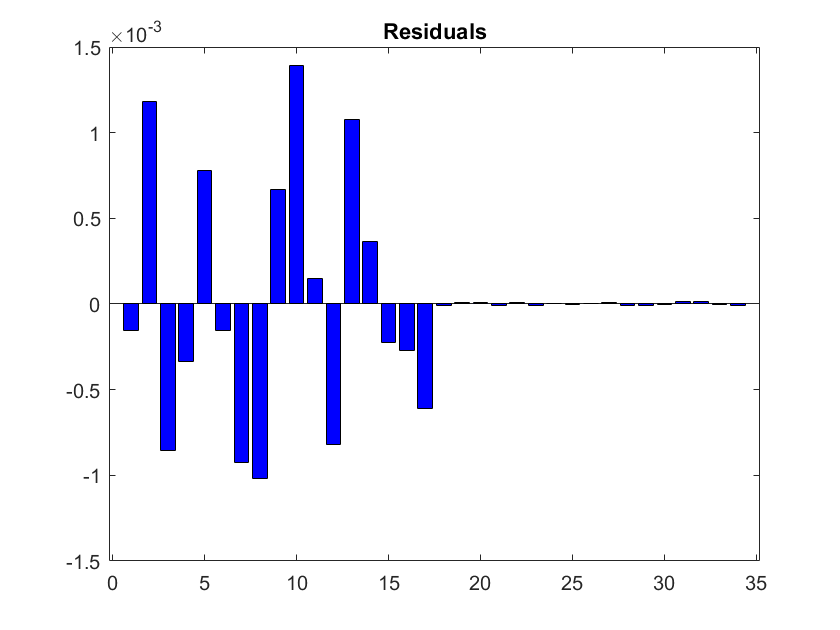



if exist("list_info") && length(list_info)==3
            [X_hat,useless]=normalizeX_(X_hat,"inverse",list_info);
            [X_0,useless]=normalizeX_(X_0,"inverse",list_info);
            Ndeal(X_,X_hat);
end
            
%plotxyc(X,L_dash,eval(F_))
figure
bar(V_hat,"b")
title("Residuals")


%Final check
if abs(L_dash_hat-eval(F_m))<delta
    disp("Good")
else
    disp("Wrong")
end

Good


**Get Result**

%Conversion
if exist("X_i",'var')
    X_hat(X_i)=mod(X_hat(X_i)*200/pi,400);
    S_X(X_i)=S_X(X_i)*200/pi;
end    
if exist("L_i",'var')
    L_0(L_i)=L_0(L_i)*200/pi;
    L_dash_hat(L_i)=mod(L_dash_hat(L_i)*200/pi,400);
    L_hat(L_i)=mod(L_hat(L_i)*200/pi,400);
    S_L_hat(L_i)=S_L_hat(L_i)*200/pi;
    V_hat(L_i)=V_hat(L_i)*200/pi;
    S_v(L_i)=S_v(L_i)*200/pi;
end

disp("=========================")

disp("6.Get Result and S_xx") 

6.Get Result and S_xx


disp("=========================")

format long


disp("Get Unknown X_hat, S_x:") 

Get Unknown X_hat, S_x:


Unknown=arrayfun(@(x) sprintf("%s",x),X_);
table(Unknown,X_0,X_hat,S_X)

ans = 21×4 table
    Unknown        X_0             X_hat                  S_X         
    _______    ___________    ________________    ____________________

    "y1000"     4590337.39    4590337.39214067     0.00048701947780534
    "y2000"    4589967.526    4589967.52961414    0.000548917241975887
    "y3000"    4590078.021    4590078.01524519    0.000524354369340984
    "y100"       4590159.8    4590159.87256871    0.000495026830375565
    "y101"       4589800.1    4589800.10840687     0.00135602174113482
    "y102"       4590163.2    4590163.25851506    0.000593127573539489
    "y103"       4589956.9    4589956.94544323    0.000762519428255683
    "x1000"    5820823.642    5820823.66275294    0.000280472138755174
    "x2000"    5820806.067    5820806.10890195    0.000497977419239764
    "x3000"    5820681.807    5820681.74434511    0.0006707832958


disp("Get Updated L_hat, S_l:") 

Get Updated L_hat, S_l:


Measurment=arrayfun(@(x) sprintf("%s",x),L_);
table(Measurment,L_0,L_hat,L_dash_hat,S_L_hat,["V_"+(1:length(V_hat))'],V_hat,S_v)

ans = 34×8 table
     Measurment        L_0           L_hat             L_dash_hat             S_L_hat            Var6             V_hat                    S_v         
    _____________    _______    ________________    ________________    ____________________    ______    _____________________    ____________________

    "DIS1000_100"    201.941    201.940846657409    201.940846657409    0.000628838746378496    "V_1"     -0.000153342591143068    0.000708032169654367
    "DIS1000_102"     175.94    175.941179179007    175.941179179007    0.000634829706711725    "V_2"       0.00117917900731734    0.000702665614420298
    "DIS2000_101"    175.288    175.287145966891    175.287145966891     0.00061752294762567    "V_3" 

**VCE**


if VCE_CONFIG==false       %~exist("Var_ind")
    [Var_ind,Var_name]=findVar();

    for i =1:length(Var_ind)
        P_dist=P_LL(Var_ind{i},Var_ind{i});
        Q_vvP_dist=Q_vvP(Var_ind{i},Var_ind{i});
        %Sub-vectors of residuals
        v_dist = V_hat_rad(Var_ind{i},1);          %sub-vector of v
        %Compute trace for sub-matrices Q_vvP_dist and Q_vvP_dir
        r_dist = trace(Q_vvP_dist);
        s_o_dist(i,1) =sqrt((v_dist'*P_dist*v_dist)/r_dist);
    end

    s_o_all=expand_V(zeros(size(L_)),Var_ind,s_o_dist);
    a_all=expand_V(zeros(size(L_)),Var_ind,1*ones(length(Var_ind),1));
    a_all=a_all.*s_o_all;
    
end
    

try
    disp("Variance Component") 
    a_all_dist=unique(a_all);
    table(Var_name,s_o_dist,a_all_dist) 
catch

    table(Measurment,s_o_all,a_all) 
end

Variance Component


ans = 2×3 table
    Var_name        s_o_dist            a_all_dist    
    ________    _________________    _________________

     "DIS"         1.072825241274    0.785957895334591
     "DIR"      0.785957895334591       1.072825241274


**Quality Assessment**

disp("Global test") 

Global test


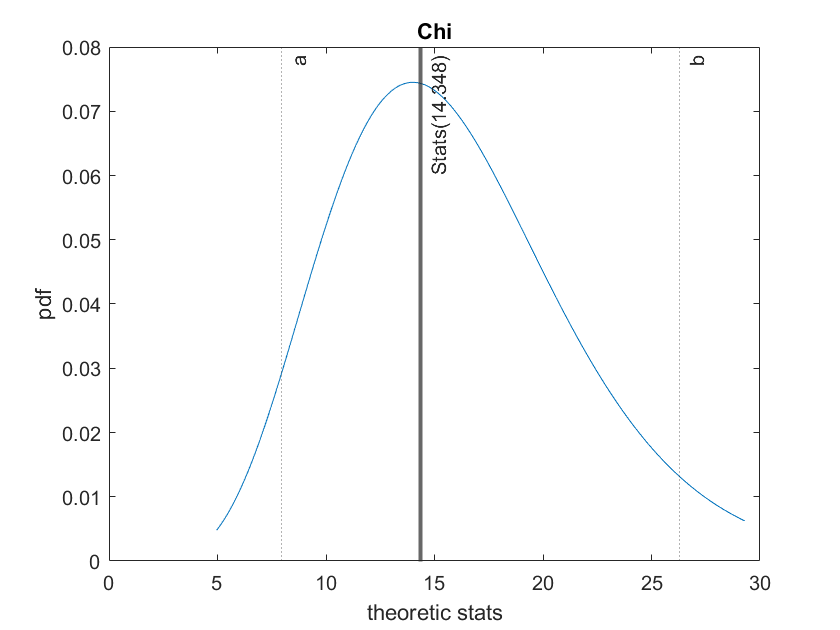

Fails to reject the H0


confidence_tool=confidence_tool();
stats=confidence_tool.statistic_test_chi(0.95, sigma_0, s_0, redundancy);




disp("Internal and external reliability parameters") 

Internal and external reliability parameters



%Check 3σ rule
mat=sqrt(S_L_hat);  

%Compute EV
r_i=diag(Q_vv*P_LL);
EV=r_i*100;

% NV
sigma_v=sigma_0*sqrt(diag(Q_vv));
NV=abs(V_hat_rad)./sigma_v;


for j=1:size(mat)
    % 3 sigma update
    if V_hat_rad(j)>(3*mat(j)) || V_hat_rad(j)<(-3*mat(j))
        sigma3_rule(j,1)="exceed 3sigma";
    else
        sigma3_rule(j,1)="Good";
    end
    % EV update
    if EV(j)<1
        EV_comment(j,1)="not controlled";
    elseif EV(j)<10
        EV_comment(j,1)="poorly controlled";
    elseif EV(j)<30
        EV_comment(j,1)="sufficiently controlled";
    elseif EV(j)<70
        EV_comment(j,1)="good controlled";   
    else
        EV_comment(j,1)="Excellent";   
    end
    
    % NV
    if NV(j)<2.5
        NV_comment(j,1)="no blunder";
    elseif NV(j)<4
        NV_comment(j,1)="blunder possible";
    else
        NV_comment(j,1)="blunder highly";   
    end  
    
end



% Potential magnitude of a blunder
GF=-V_hat_rad./r_i;
 
% Lower boundary value for blunders
GRZW=ones(no_n,1); % help matlab with memory by making a empty matrix
for i=1:no_n
    GRZW(i,1)=sigma_0*4.13/sqrt(r_i(i,1)*P_LL(i,i));
end



GF(L_i,1) = GF(L_i,1)*200/pi;

GRZW(L_i,1)=GRZW(L_i,1)*200/pi;   % we change those measurments that were  amgles


P_diag=diag(P_LL);
dd=ones(size(r_i));
rw=zeros(size(r_i));


for i=1:length(L_i)
    target_name=Measurment(L_i(i));
    target_name=regexp(target_name,'\d*\.?\d*','match');
    num_1=target_name{1};
    num_2=target_name{2};
    
    %get dis
    if exist(["DIS"+num_1+"_"+num_2])
        dd(L_i(i))=eval(["DIS"+num_1+"_"+num_2]);
    elseif exist(["DIS"+num_2+"_"+num_1])
        dd(L_i(i))=eval(["DIS"+num_2+"_"+num_1]);
    else
        warning("there is no "+["DIS"+num_2+"_"+num_1])
        dd(L_i(i))=1;
    end
    Psum_i=find(contains(Measurment,["DIR"+num_1+"_"]));
    PSum=sum(P_diag(Psum_i));
    rw(L_i(i))=P_diag(L_i(i))/PSum;
end

r_i_w=1-r_i;
r_i_w=(r_i_w-rw).*dd;

EP=r_i_w.*GF;

table(Measurment,V_hat_rad,S_L_hat,sigma3_rule,EV,EV_comment,GF,GRZW,NV,NV_comment,EP)

ans = 34×11 table
     Measurment            V_hat_rad                S_L_hat           sigma3_rule           EV                  EV_comment                     GF                     GRZW                   NV             NV_comment              EP          
    _____________    _____________________    ____________________    ___________    ________________    _________________________    _____________________    ___________________    _________________    ____________    _____________________

    "DIS1000_100"    -0.000153342591143068    0.000628838746378496      "Good"       55.9030751735504    "good controlled"   